# Simulation used in support of CDRL A009

clearvars

## Simulation

Simulation has been used on this task to support testing and understanding of the underlining physics and mechanisms of the use of over the horizon RADAR (OTHR.) The reliance of simulation is a philosophy used in object tracking as shown in the extensively used Kalman filtering, which relies on the repeated calls to a "model" to find a solution.

The imaginary scenario created for testing is a ballistic model of a football being shot from Michigan to Ohio at very high speed.

### Simulation Operating Parameters 

Here we define the simulation operating parameters in the form of a structure that can be passed between simulation modules and routines.

% Define the data directory for this simulation
SOP.datDire = "C:\Users\pbergman\GIT25\ZDA";
SOP.bgnLevel = 0.0; % Background noise.

## Setup Ohio

Define target location in Ohio.

latOH = EARTH.GROUNDZ(1);
lonOH = EARTH.GROUNDZ(2);
altOH = EARTH.GROUNDZ(3);
[OHx, OHy, OHz] = geodetic2ecef( wgs84Ellipsoid, latOH, lonOH, altOH );
disp( table(latOH, lonOH, altOH) );

    latOH     lonOH     altOH
    ______    ______    _____

    40.002    -83.02     275 



% Create a KML file.

kmlFile = strcat(SOP.datDire, '\O_H_I_O.kml');
kmlwrite(kmlFile, geopoint( latOH, lonOH ) );

## Setup Michigan

Define launch location in Michigan.

latM = EARTH.GROUNDM(1);
lonM = EARTH.GROUNDM(2);
altM = EARTH.GROUNDM(3);
[Mx, My, Mz] = geodetic2ecef( wgs84Ellipsoid, latM, lonM, altM );
disp( table(latM, lonM, altM) );

     latM      lonM      altM
    ______    _______    ____

    42.266    -83.749    230 



% Create a KML file.
kmlFile = strcat(SOP.datDire,'\N_M_E.kml');
kmlwrite(kmlFile, geopoint( latM, lonM ) );

## Define opponents' bearings from each other.

[targetMBearing, ~, ~]  = geodetic2aer( latM,  lonM,  altM, latOH, lonOH, altOH, wgs84Ellipsoid)

targetMBearing =        346.56


[targetOHBearing, ~, ~] = geodetic2aer(latOH, lonOH, altOH,  latM,  lonM,  altM, wgs84Ellipsoid)

targetOHBearing =        166.08


## Define Simulated Antenna Array

### Existing U.S. Navy Antenna

Use the Relocatable OTH (ROTH) antenna, in Kent Virginia, as an example. Two sets of 16 elements.

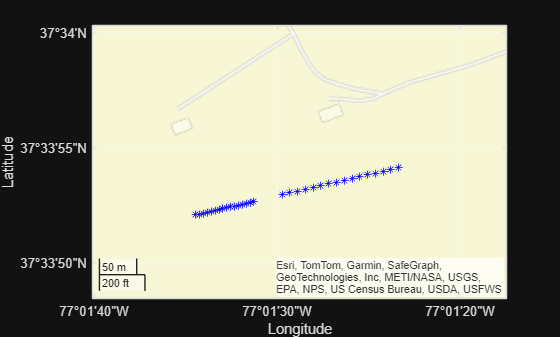

[lat1_, lon1_, lat2_, lon2_] = ROTH.kentElementPositions();
geoplot([lat1_ lat2_], [lon1_ lon2_],"*b")
geobasemap streets
geolimits( [37.56346 37.56676], [-77.02781 -77.02151] );

thePoints_ = geopoint([lat1_ lat2_], [lon1_ lon2_]);
kmlFile = strcat(SOP.datDire, '\originalLine.kml');
kmlwrite(kmlFile, thePoints_);

### ROP

Here we define a set of RADAR operating parameters (ROP) for the simulated U.S. Navy antenna.  The ROP is in the form of a structure that can be passed between simulation modules and routines.

ROP.Bw  =   4e3;           % Linear Frequency Modulation (LFM) band width. 
ROP.Fc  =  10e6;           % Center frequency of Pulse ( May have a question here.)
ROP.Fs  = 32000;           % RADAR digital data sample rate.
ROP.Swr = 100e3;           % Linear Frequency Modulation (LFM) sweep rate.
ROP.Tau = ROP.Bw./ROP.Swr; % Time of sweep.
% ROP.TTag = int64(posixtime( datetime('now','TimeZone','UTC')));
ROP.TTag = 1762978571;
ROP.TText = datetime(ROP.TTag, 'ConvertFrom', 'posixtime', 'Format', 'yyyyMMdd_hhmmss');
ROP.TText = char(ROP.TText);

### Position Antenna Array

For this scenario we will move the simulated ROTH antenna to a location in Ohio.

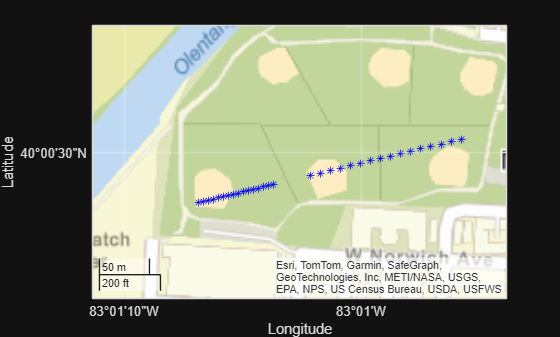

[lat1_, lon1_, lat2_, lon2_] = ROTH.ohsElementPositions();

ohsdAntennaTilt = atan2d( lat1_(end) - lat1_(1), lon1_(end) - lon1_(1) );

geoplot([lat1_ lat2_], [lon1_ lon2_], "*b");
geobasemap streets;
geolimits([40.00702 40.00948],[-83.01982 -83.01496]);
hold off;

The antenna array will have antennas at the following locations:

thePoints_ = geopoint([lat1_ lat2_], [lon1_ lon2_]);
theTable = table( ...
  thePoints_.Latitude.', ...
  thePoints_.Longitude.', ...
  VariableNames=["Lat" "Lon"], ...
  RowNames=string(1:32));
disp(theTable(1:4,:));

          Lat        Lon  
         ______    _______

    1    40.008    -83.017
    2    40.008    -83.017
    3    40.008    -83.017
    4    40.008    -83.017



fprintf(".\n.\n.\n");

.
.
.


disp(theTable(29:32,:));

           Lat        Lon  
          ______    _______

    29    40.008    -83.018
    30    40.008    -83.018
    31    40.008    -83.018
    32    40.008    -83.018



% KML for defensive line.
kmlFile = strcat(SOP.datDire,  '\defensiveLine.kml');
kmlwrite(kmlFile, thePoints_);

## Kick Off

These are the equations for motion used in this simulation.

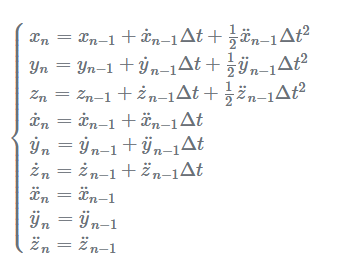

[https://kalmanfilter.net/kalmanmulti.html](https://kalmanfilter.net/kalmanmulti.html)

## Calculate initial velocity.

MissouriMuzzleVelocity = 820;       % Meters/Second.
distanceInOneSecond = 820;          % Meters.
firingElevation = 45.0;

[x0, y0, z0] = geodetic2ecef( wgs84Ellipsoid, latM, lonM, altM );

[x1, y1, z1] = aer2ecef( ...
  targetOHBearing, ...
  firingElevation, ...
  distanceInOneSecond, ...
  latM, lonM, altM, ...
  wgs84Ellipsoid);

displacementVector = [x1, y1, z1]-[x0, y0, z0];
velocityUnitVector = displacementVector./norm(displacementVector);

## Calculate ballistic path.

% Mx;                                                      % Position
% My;                                                      % 
% Mz;                                                      % 

tmp_ = velocityUnitVector.*MissouriMuzzleVelocity;         % Velocity
vx = tmp_(1);                                              %
vy = tmp_(2);                                              %
vz = tmp_(3);                                              %

tt = 150;     % Total time in seconds.
dt = .04;     % Delta time.
t_ = 0:dt:tt; % Time series.

[pBuffer, vBuffer] = ballisticPath(Mx, My, Mz, vx, vy, vz, tt, dt); % Calculate Ballistic path.


## Calculate Slant Range

% Slant Range                            x             y             z
[az_, el_, slantRange_] = ecef2aer(pBuffer(:,1), pBuffer(:,2), pBuffer(:,3), latOH, lonOH, altOH, wgs84Ellipsoid);

## Calculate Slant Velocity

The following are in Earth Centered Earth Fixed coordinates:

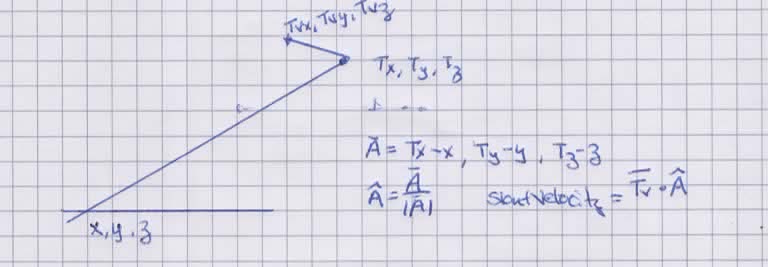


$$\bar {OriginPosition} =  (x,y,z)$$



$$
\bar{TargetPosition} = (T_x,T_y,T_z)
$$



$$
\bar{TargetVelocity = (T_{vx},T_{vy},T_{vz})
$$



$$\bar A = (T_x -x. T_y-y, T_z-z)$$



$$\hat A = \frac { \bar A }{| \bar A |}
$$



$$\bar {slantVelocity} = \bar T_v \cdot \hat A
$$



$$\bar T_v \cdot \hat A

= 

T_{vx} \cdot \hat A_x + 

T_{vy} \cdot \hat A_y +
 
T_{vz} \cdot \hat A_z  $$


%slantVelocity_
tmpVector = pBuffer - [OHx, OHy, OHz];
tmpVector_hat = zeros(size(tmpVector));
slantVelocity_ = zeros(length(tmpVector),1);

for ii = 1:length(tmpVector)
  tmpVector_hat(ii,:) = tmpVector(ii,:)/norm(tmpVector(ii,:));
end

for ii = 1:length(tmpVector)
  slantVelocity_(ii) = dot( vBuffer(ii,:), tmpVector_hat(ii,:) ); 
end


## Plot Ballistic Path

Plot the ballistic path.  Does it look correct?

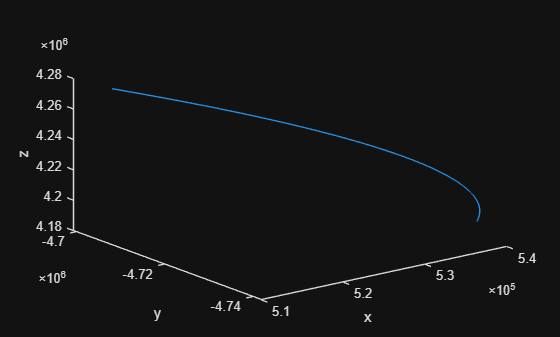

plot3( pBuffer(:,1), pBuffer(:,2), pBuffer(:,3) );
xlabel("x"); 
ylabel("y");
zlabel("z");

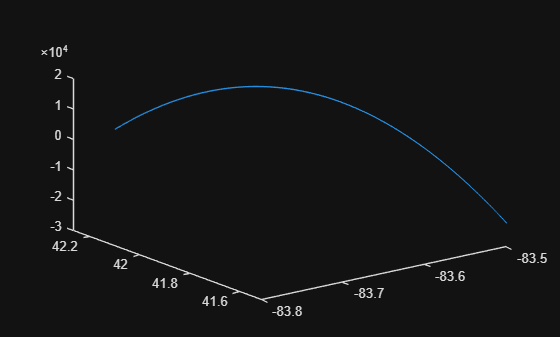

[lats, lons, alts] = ecef2geodetic(wgs84Ellipsoid, pBuffer(:,1), pBuffer(:,2), pBuffer(:,3));
plot3(lons,lats,alts);

plotInteractiveMap = false;

if plotInteractiveMap
  uif = uifigure;                %#ok<UNRCH>
  g = geoglobe(uif);
  geoplot3(g, lats, lons, alts); 
end

## Make Range Bin Calculation

Calculate the range per range bin :

DO NOT USE THIS: $dR = \frac{C}{2 \cdot Bw}$


$$Seconds Per Sweep = \frac{ Bandwidth }{SweepRate}$$



$$RangePerSweep = C  \cdot SecondsPerSweep$$



$$RangePerReturn = \frac{1}{2} \cdot RangePerSweep$$



$$SamplesPerSweep = Fs \cdot SecondsPerSweep$$



$$RangePerBin = \frac{RangePerReturn}{SamplesPerSweep}$$



$$RangeBin = \frac{ SlantRange }{ RangePerBin }$$


rangeBin_ = ROTH.slantRange2RangeBin(slantRange_, ROP.Bw, ROP.Swr, ROP.Fs);

## Calculate Doppler

Calculate doppler of the reflected Linear Frequency Modulated RADAR pulse by:

$\Delta f = \pm \frac{2 \cdot v}{c} \cdot f \cdot cos(\theta)$`   Hertz`

`Where:`

  $\Delta f$` is the frequency shift, up or down, depending on whether the target is approaching or receding.`

  $v$`   is the speed of the target`

  $c$`   is the speed of light in a vacuum`

  $\theta
$`   is the angel between the target direction of motion and the radar look direction.`

doppler_ = ROTH.calculateDoppler(-slantVelocity_, ROP.Fc);

## Create Results Table

varNames = {...
  'SECONDS', ...
  'SLANT RANGE(M)',...
  'SLANT VELOCITY(M/S)',...
  'DOPPLER (Hz)',...
  'RANGE BIN',...
  'RB',...
  'AZIMUTH',...
  'ELEVATION'};

simTable = table( ...
  t_.', ...
  slantRange_, ...
  slantVelocity_, ...
  doppler_, ...
  rangeBin_, ...
  round(rangeBin_), ...
  az_, ...
  el_, ...
  'VariableNames', varNames);

format short g
disp(simTable(:,:));

    SECONDS    SLANT RANGE(M)    SLANT VELOCITY(M/S)    DOPPLER (Hz)    RANGE BIN    RB    AZIMUTH     ELEVATION 
    _______    ______________    ___________________    ____________    _________    __    _______    ___________

         0       2.5879e+05            -568.02             37.894        55.246      55    346.56         -1.1749
      0.04       2.5877e+05            -567.98             37.891        55.242      55    346.56         -1.1697
      0.08       2.5874e+05            -567.93             37.888        55.237      55    346.56         -1.1645
      0.12       2.5872e+05            -567.88             37.885        55.232      55    346.56         -1.1592
      0.16        2.587e+05            -567

## Generate Radar Return

Generate the RADAR return.

[ROP, lfmSweep_, radarReturn_] = ROTH.createRadarReturn( t_, rangeBin_, doppler_, el_, ROP);

radarReturnFileName = ROTH.createDataFileName( 'radarReturn', ROP);
save( radarReturnFileName, "ROP", "radarReturn_", "az_" );

## Miscellaneous.

### Kent Virginia

[https://www.google.com/maps/@37.5642715,-77.0262546,1267m/data=!3m1!1e3?authuser=0&entry=ttu&g_ep=EgoyMDI1MTAwNC4wIKXMDSoASAFQAw%3D%3D](https://www.google.com/maps/@37.5642715,-77.0262546,1267m/data=!3m1!1e3?authuser=0&entry=ttu&g_ep=EgoyMDI1MTAwNC4wIKXMDSoASAFQAw%3D%3D)

### Southern Virginia

[https://www.google.com/maps/@36.5593599,-76.2724121,3309m/data=!3m1!1e3?authuser=0&entry=ttu&g_ep=EgoyMDI1MTAwNC4wIKXMDSoASAFQAw%3D%3D](https://www.google.com/maps/@36.5593599,-76.2724121,3309m/data=!3m1!1e3?authuser=0&entry=ttu&g_ep=EgoyMDI1MTAwNC4wIKXMDSoASAFQAw%3D%3D)

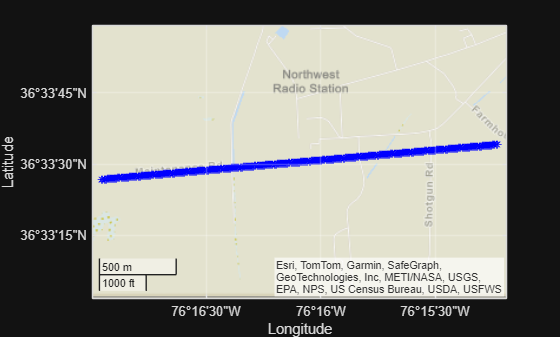

lat1_ = linspace( +36.55744391067608, +36.55947821030294, 373);
lon1_ = linspace( -76.28259943083229, -76.25382237154776, 373);
geoplot( lat1_, lon1_,"*b" )

geobasemap streets

thePoints = geopoint(lat1_,lon1_);
kmlFile = strcat(SOP.datDire, '\southVirginia.kml');
kmlwrite(kmlFile, thePoints);

### South Texas

[https://www.google.com/maps/@27.5261853,-98.1094048,2174m/data=!3m1!1e3?authuser=0&entry=ttu&g_ep=EgoyMDI1MTAwNi4wIKXMDSoASAFQAw%3D%3D](https://www.google.com/maps/@27.5261853,-98.1094048,2174m/data=!3m1!1e3?authuser=0&entry=ttu&g_ep=EgoyMDI1MTAwNi4wIKXMDSoASAFQAw%3D%3D)

lat1_ = linspace( +27.526886150916884, +27.527698301081564, 16);
lon1_ = linspace( -98.110924116347120, -98.109710167872140, 16);

lat2_ = linspace( +27.526052097037358, +27.526491651228355, 16);
lon2_ = linspace( -98.111868671440280, -98.111228522083540, 16);

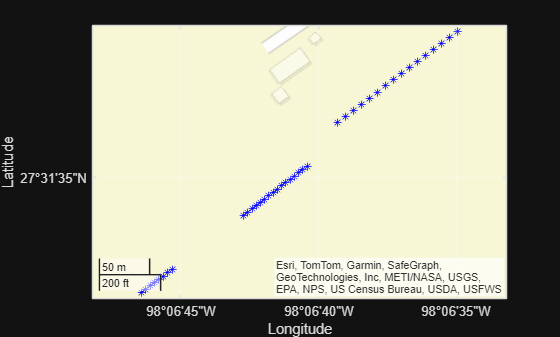

lat3_ = linspace( +27.525362293985864, +27.525566589738443, 8);
lon3_ = linspace( -98.112898382748000, -98.112590307650460, 8);
geoplot([lat1_ lat2_ lat3_], [lon1_ lon2_ lon3_],"*b");

geobasemap streets

thePoints = geopoint([lat1_ lat2_ lat3_], [lon1_ lon2_ lon3_]);
kmlFile = strcat(SOP.datDire, '\southTexas.kml');
kmlwrite(kmlFile, thePoints);

### Puerto Rico

[https://www.google.com/maps/@18.0965838,-65.5159305,1774m/data=!3m1!1e3?authuser=0&entry=ttu&g_ep=EgoyMDI1MTAwNC4wIKXMDSoASAFQAw%3D%3D](https://www.google.com/maps/@18.0965838,-65.5159305,1774m/data=!3m1!1e3?authuser=0&entry=ttu&g_ep=EgoyMDI1MTAwNC4wIKXMDSoASAFQAw%3D%3D)

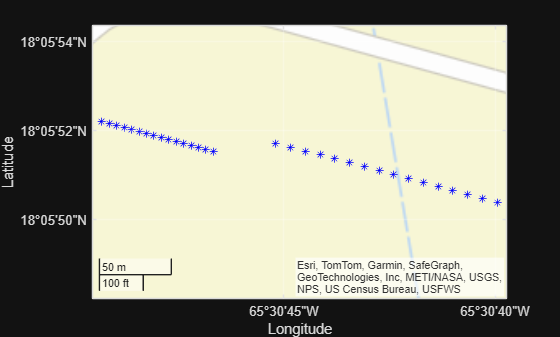

lat1_ = linspace( +18.097331290141742, +18.097701419695145, 16);
lon1_ = linspace( -65.511099035241190, -65.512552849221780, 16);
lat2_ = linspace( +18.097835687987477, +18.097646125327753, 16);
lon2_ = linspace( -65.513695300150000, -65.512963420784360, 16);
geoplot([lat1_ lat2_], [lon1_ lon2_],"*b")
geobasemap streets

thePoints = geopoint([lat1_ lat2_], [lon1_ lon2_]);
kmlFile = strcat(SOP.datDire, '\puertoRico.kml');
kmlwrite(kmlFile, thePoints);

### ROTH Coverage

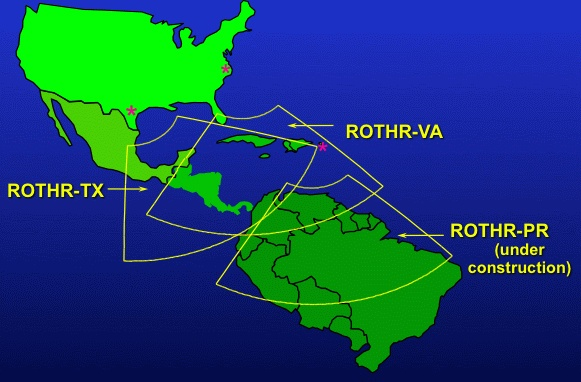

[https://upload.wikimedia.org/wikipedia/commons/0/0c/Rothr_range.jpg](https://upload.wikimedia.org/wikipedia/commons/0/0c/Rothr_range.jpg)

Other stuff.

[https://nuke.fas.org/guide/usa/airdef/an-tps-71.htm](https://nuke.fas.org/guide/usa/airdef/an-tps-71.htm)

[https://en.wikipedia.org/wiki/Over-the-horizon_radar](https://en.wikipedia.org/wiki/Over-the-horizon_radar)

18.097699587557823, -65.51216735221028 Puerto Rico

36.55746612562705, -76.2825961465554 Virginia

36.55741137231524, -76.28258997152555

36.55947714912853, -76.25381835158431

## Ballistic Path Function

function [pBuff,vBuff] = ballisticPath(x, y, z, vx, vy, vz, tt, dt)
% Create ballistic path from initial position (x,y,z) and initial velocity (vx, vy, vz) 
% and total time (tt) and time step (dt.)
%------------------------------------------------------------------------------------------------
  t_ = 0:dt:tt;                                                      % Time series.

  p_x_new = x;                                                       % Position
  p_y_new = y;                                                       % 
  p_z_new = z;                                                       % 
  
  v_x_new = vx;                                                      % Velocity
  v_y_new = vy;                                                      %
  v_z_new = vz;                                                      %
  
  re_new = norm([p_x_new p_y_new p_z_new]);                          % Acceleration from Gravity.
  re_hat = [p_x_new p_y_new p_z_new]/re_new;                         %
  g_new  = -UNIVERSE.G*(EARTH.MASS + 100)./(re_new*re_new);          %
  g_x_new = g_new.*re_hat(1);                                        %
  g_y_new = g_new.*re_hat(2);                                        %
  g_z_new = g_new.*re_hat(3);                                        %
  
  pBuff = zeros( length(t_), 3 );
  vBuff = zeros( length(t_), 3 );
  
  for ii = 1:length(t_)
    p_x = p_x_new;
    p_y = p_y_new;
    p_z = p_z_new;
    
    v_x = v_x_new;
    v_y = v_y_new;
    v_z = v_z_new;
    
    g_x = g_x_new;
    g_y = g_y_new;
    g_z = g_z_new;
    
    p_x_new = p_x + v_x*dt + 0.5 *g_x*dt*dt;
    p_y_new = p_y + v_y*dt + 0.5 *g_y*dt*dt;
    p_z_new = p_z + v_z*dt + 0.5 *g_z*dt*dt;
    
    v_x_new = v_x + g_x*dt;
    v_y_new = v_y + g_y*dt;
    v_z_new = v_z + g_z*dt;
    
    re_new = norm([p_x_new p_y_new p_z_new]);
    re_hat = [p_x_new p_y_new p_z_new]/re_new;
    g_new  = -UNIVERSE.G*(EARTH.MASS + 100)./(re_new*re_new);
    
    g_x_new = g_new.*re_hat(1);
    g_y_new = g_new.*re_hat(2);
    g_z_new = g_new.*re_hat(3);
  
    pBuff(ii,1) = p_x;
    pBuff(ii,2) = p_y;
    pBuff(ii,3) = p_z;
  
    vBuff(ii,1) = v_x;
    vBuff(ii,2) = v_y;
    vBuff(ii,3) = v_z;
  
  end
end

# `%------------------------------------------------------------------------------`

# `% OLD STUFF`

# `%------------------------------------------------------------------------------`

## Inverse Beamform

% [lat1_, lon1_, ~, ~] = ROTH.ohsElementPositions();
% alt1_ = lat1_.*0.0;
% 
% elementData = ROTH.inverseBeamForm( rrStruct, ROP.Fc, az_, lat1_, lon1_, alt1_);
% 
% % [lat1_, lon1_, ~, ~] = ROTH.ohsElementPositions();
% % varNames = {'SECONDS', 'AZIMUTH', 'AZ+TILT', 'SIN(AZ+TILT)'};
% % lambda = UNIVERSE.C/ROP_Fc;
% % azPlus = az_ + ohsdAntennaTilt;
% % targetBearingTable = table(t_.', az_, azPlus, sind(azPlus), 'VariableNames', varNames);
% % [x0, y0, z0] = geodetic2ecef( wgs84Ellipsoid, lat1_(1), lon1_(1), 0.0 );
% % [x1, y1, z1] = geodetic2ecef( wgs84Ellipsoid, lat1_(end), lon1_(end), 0.0 );
% % separation = sqrt( (x0-x1)^2 +  (y0-y1)^2 + (z0-z1)^2 )./length(lat1_);
% % elementNumber = -7.5:1.0:+7.5;
% % elementDisplacement = elementNumber .* separation;
% % elementPhaseOffset = 2.0 .* pi .* elementDisplacement .* sind(azPlus) ./ lambda;
% % elementPhaseWeight = cos(elementPhaseOffset) + sin(elementPhaseOffset)*1i;

## Beamform

## Pulse Compression ( Matched Filter )

% pulseCompress_ = ROTH.matchedFilter( radarReturn_, lfmSweep_);
% 
% userPro = getenv("USERPROFILE");
% git2025 = strcat(userPro,'\GIT25');
% dataDir = strcat(git2025,'\ZData00');
% saveFileName = [dataDir '\simOutput.mat'];
% save( saveFileName, "rrStruct", "pulseCompress_" );


## Doppler


$$f_o  =  f_s   \cdot  \frac {C}  {C+v}$$


Where:

$f_o $ is observed frequency

$f_c$ is center frequency of Linear Frequency Modulated signal

C is the speed of light

v is the velocity of source